## Linear Regression in MATLAB

#### Setup our Data 

Load in our data

data = load("ex1data2.txt");

Setup our input data 

X = data(:, 1:end-1);

Add column of ones to our input data

X = [ones(size(X, 1), 1), X];

Setup our output data

y = data(:, end);

Initialize our theta values

theta = zeros(1, size(X,2));

#### Feature Scaling

Scale our Features

[X_norm, mu, sigma] = scale_features(X);

Initialize lambda

lam = 0

lam =      0


#### Perform Gradient Descent

Initialize learning rate

alpha = 0.03;

Initialize the number of iterations

num_iters = 1500;

Perform our gradient Descent

[theta, J_History] = gradient_descent(X_norm, y, theta, alpha, num_iters, lam);

Plot our J_History

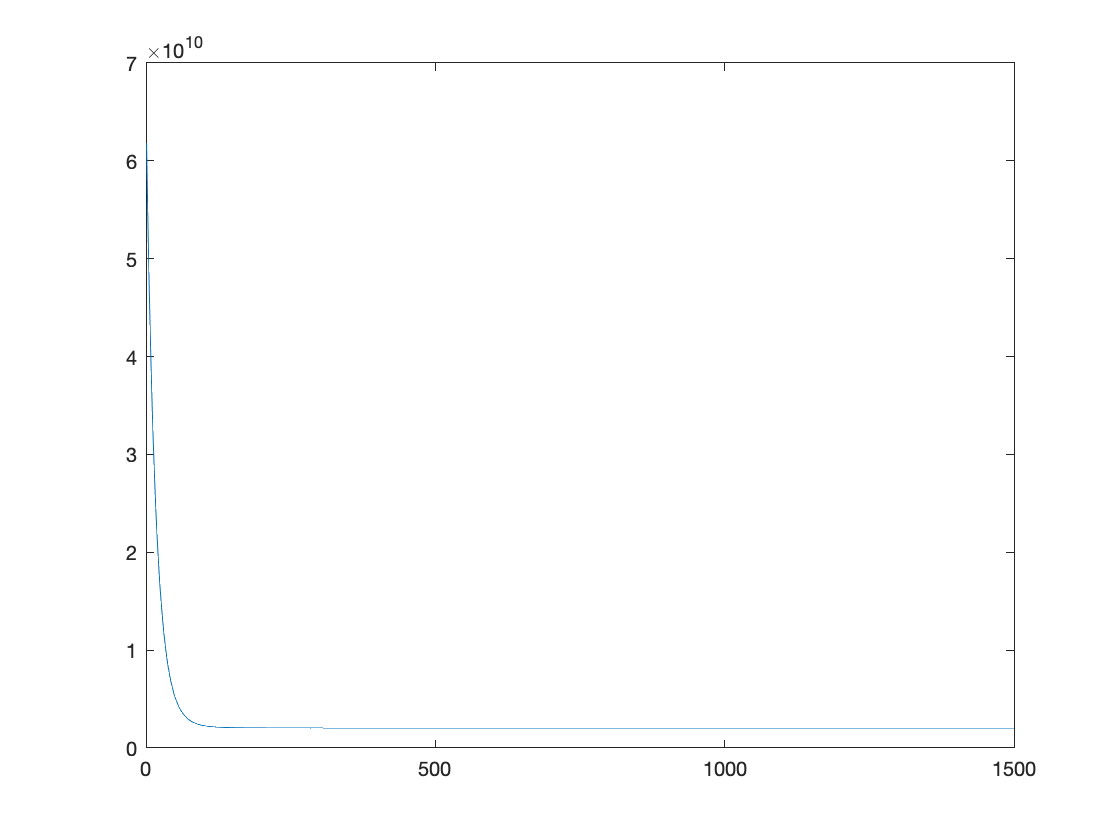

plot(J_History);

**Theta Calculated Via Gradient Descent:**

disp(theta);

          340412.659574467          110631.050080853          -6649.4740728264



#### Test our Predictions

**Price of house that's 1650 sqrt feet and has 3 windows as calculated by gradient descent: **

test = [1, 1650, 3];
disp("Price of House as predicted by gradient descent: $" + predict(test, theta, mu, sigma))

Price of House as predicted by gradient descent: $293081.4644


**Price of house that's 1650 sqrt feet and has 3 windows as calculated by normal equation:**

norm_theta = normal_equation(X, y);
disp("Price of House as predicted by Normal Equation: $" + test * norm_theta')

Price of House as predicted by Normal Equation: $293081.4643
